close("all"); clear; clc;

x = OptimizationVariables(sym('t'),4,1);
x.ParameterLowerBound = 0;
x.ControlLowerBounds = -4;
x.ControlUpperBounds = 4;

p = [-9.81,0.3,0.5,0.2].';
plant = Plant(x,@invertedPendulumAndCart,p.');

J = Cost(x,@(x,u)1 + 0.*u(1,:));

ocp = OptimalControlProblem(x,J,plant);
ocp.InitialTime = 0;
% ocp.FinalTime = 3;
ocp.InitialState = [0;deg2rad(180);0;0];
ocp.FinalState = [3;0;0;0];
disp(ocp)

MINIMIZE:


$$\int_{0}^{t_{f}}1\mathrm{d}t$$

SUBJECT TO:

Dynamic constraints:


$$\left[\begin{array}{c} \frac{\partial }{\partial t}x_{1}\left(t\right)=x_{3}\left(t\right)\\ \frac{\partial }{\partial t}x_{2}\left(t\right)=x_{4}\left(t\right)\\ \frac{\partial }{\partial t}x_{3}\left(t\right)=\frac{8829\,\cos\left(x_{2}\left(t\right)\right)\,\sin\left(x_{2}\left(t\right)\right)}{250000\,\left(\frac{9\,{\cos\left(x_{2}\left(t\right)\right)}^{2}}{2500}-\frac{63}{5000}\right)}-\frac{\frac{27\,\sin\left(x_{2}\left(t\right)\right)\,{x_{4}\left(t\right)}^{2}}{25000}+\frac{9\,u_{1}\left(t\right)}{500}}{\frac{9\,{\cos\left(x_{2}\left(t\right)\right)}^{2}}{2500}-\frac{63}{5000}}\\ \frac{\partial }{\partial t}x_{4}\left(t\right)=\frac{3\,\cos\left(x_{2}\left(t\right)\right)\,\left(\frac{3\,\sin\left(x_{2}\left(t\right)\right)\,{x_{4}\left(t\right)}^{2}}{50}+u_{1}\left(t\right)\right)}{50\,\left(\frac{9\,{\cos\left(x_{2}\left(t\right)\right)}^{2}}{2500}-\frac{63}{5000}\right)}-\frac{20601\,\sin\left(x_{2}\left(t\right)\right)}{50000\,\left(\frac{9\,{\cos\left(x_{2}\left(t\right)\right)}^{2}}{2500}-\frac{63}{5000}\right)} \end{array}\right]$$

Parameter bounds:


$$1<t_{f}$$

Control bounds:


$$\left(-4\leq u_{1}\left(t\right)\right)\leq 4$$

N = 33;
cc = DirectCollocation(@trapezoidalDefect,ocp,N);
x10 = linspace(ocp.InitialState(1),ocp.FinalState(1),N);
x20 = linspace(ocp.InitialState(2),ocp.FinalState(2),N);
x30 = linspace(ocp.InitialState(1),ocp.FinalState(1),N);
x40 = linspace(ocp.InitialState(2),ocp.FinalState(2),N);
x0 = [x10;x20;x30;x40];
u0 = linspace(1,-1,N);
cc.initialGuess(x0,u0);

opts = optimoptions("fmincon", ...
    "MaxIterations", 1E04, ...
    "MaxFunctionEvaluations",1E06 ...
    );
[t0,tf,x,u] = cc.optimize(opts);


Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


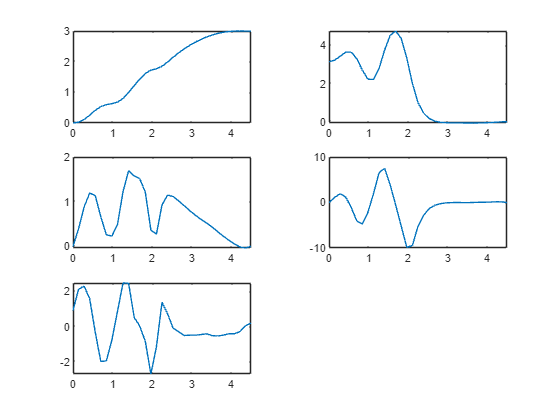

results = [x;u];
tiledlayout(3,2);
for i = 1:size(results,1)
    nexttile;
    plot(linspace(t0,tf,N),results(i,:));
    xlim([0,tf]);
    box("on");
end